Całka oznaczona (Riemana) jest z definicji równa:

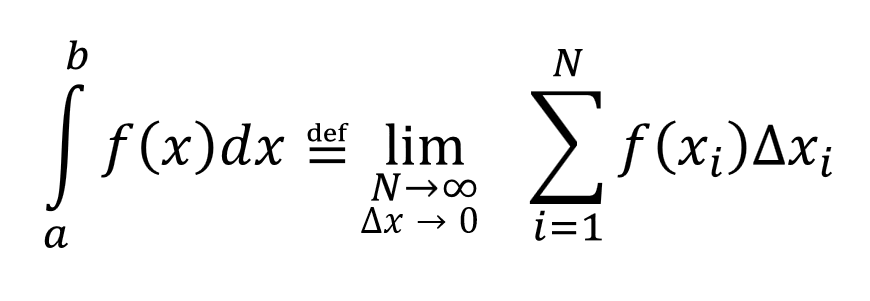

Gdzie podział przedziału (a,b) może być dowolny (byle poszczególne podprzedziały były infinitezymalnie małe). Dowolny również może być wybór konkretnego xi, dla którego obliczana będzie wartość f(xi) (byle by należał do odpowiedniego podprzedziału).

W implementacji numerycznej, gdzie wartość całki przybliża skończona suma, sposób podziału przedziału (a,b) na podprzedziały, jak i sposób obliczenia f(xi) (np. poprzez wybór xi) odgrywa kluczową rolę, ponieważ przekłada się bezpośrendio na dokładność uzyskanego wyniku (bardziej precyzyjnie mówiąc na szybkość uzyskania wyniku o założonej dokładności).

Obrazuje to następujący przykład (przyjęto równomierny podział przedziału (a,b) na podprzedziały), w różny sposób natomiast jest obliczana wartość f(xi).

- Wybierz funkcję podcałkową.

- Zdefiniuj liczbę podprzedziałów k.

- Uruchom skrypt.

- Pomyśl nad uzyskanymi wynikami i uruchom skrypt jeszcze raz dla innych funkcji i różnej liczby podprzedziałów.

- Możesz przejrzeć kod, a także spróbować go modyfikować w celu uzyskania ciekawych rezultatów.

- Możesz również sprawdzić wartość całki we własnoręcznie zdefiniowanym przedziale, w tym celu odhacz opcję "Uruchom w domyślnym przedziale" i podaj granice przedziału w konsoli po uruchomieniu skryptu.

clear all;
close all;
%zwybór funkcji, której będzie obliczana całka
syms f(x)
f(x)=sin(x)

$$f(x) = \sin\left(x\right)$$



%Uruchom w domyślnym przedziale
deafVal=true;
%umieszczanie wartosci calki na wykresach
intVis=true;

%zdefiniuj liczbę podprzedziałów do obliczenia całki
k=10;
 

if deafVal==true
    if strcmp(string(char(f(x))),"sin(x)")
        a=0
        b=10
    end
    if strcmp(string(char(f(x))),"x^3 - 2*x^2 - 5*x - 3")
        a=-3
        b=4
    end
    if strcmp(string(char(f(x))),"3*x^4 - 2*x + x^6")
        a=-1
        b=1
    end
    if strcmp(string(char(f(x))),"exp(x)")
        a=1
        b=5
    end        
else
    a=input("Podaj lewy kraniec przedzialu:")
    b=input("Podaj prawy kraniec przedzialu:")
    if a>=b
        display("Prawy kraniec przedziału musi być liczbą większą od lewego krańca.")
        return
    end
end

a = 0

b = 10


calka_dokladna=double(int(f,a,b))

calka_dokladna = 1.8391

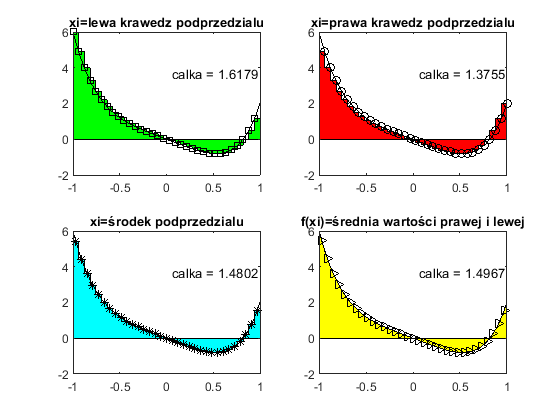


Q=3;
x1=linspace(a,b,abs(b-a)*100);
[min_f,min_i]=min(double(f(x1)));
[max_f,max_i]=max(double(f(x1)));
xmin=a+(min_i-1)/100;
xmax=a+(max_i-1)/100;
x3=repelem(linspace(a,b,k+1),2);
d_podprze=(b-a)/k;
pkt_l=(a:d_podprze:b-d_podprze);
pkt_r=(a+d_podprze:d_podprze:b);
pkt_m=(a+d_podprze/2:d_podprze:b-d_podprze/2);
calka_num_l=sum(double(f(pkt_l)))*d_podprze;
calka_num_r=sum(double(f(pkt_r)))*d_podprze;
calka_num_m=sum(double(f(pkt_m)))*d_podprze;
calka_num_mv=sum(double(f(pkt_l)+f(pkt_r))/2)*d_podprze;

figure()
subplot(2,2,1)
fill(x3,[0,double(f(repelem(pkt_l,2))),0],'g')
hold on
plot(x1,double(f(x1)),'k',pkt_l,double(f(pkt_l)),'sk')
title('xi=lewa krawedz podprzedzialu')
if intVis==true
    txt=['calka = ' num2str(calka_num_l)];
    text(xmin,min_f+(max_f-min_f)*2/3,txt,'HorizontalAlignment','center')
end
hold off
subplot(2,2,2)
fill(x3,[0,double(f(repelem(pkt_r,2))),0],'r')
hold on
plot(x1,double(f(x1)),'k',pkt_r,double(f(pkt_r)),'ok')
title('xi=prawa krawedz podprzedzialu')
if intVis==true
    txt=['calka = ' num2str(calka_num_r)];
    text(xmin,min_f+(max_f-min_f)*2/3,txt,'HorizontalAlignment','center')
end
hold off
subplot(2,2,3)
fill(x3,[0,double(f(repelem(pkt_m,2))),0],'c')
hold on
plot(x1,double(f(x1)),'k',pkt_m,double(f(pkt_m)),'*k')
title('xi=środek podprzedzialu')
if intVis==true
    txt=['calka = ' num2str(calka_num_m)];
    text(xmin,min_f+(max_f-min_f)*2/3,txt,'HorizontalAlignment','center')
end
hold off
subplot(2,2,4)
for i=1:numel(pkt_l)
    y1(2*i-1)=pkt_l(i);
    y1(2*i)=pkt_r(i);
end
fill(x3,[0,double(f(y1)),0],'y')
hold on
plot(x1,double(f(x1)),'k',pkt_m,double(f(pkt_l)+f(pkt_r))/2,'>k')
title('f(xi)=średnia wartości prawej i lewej')
if intVis==true
    txt=['calka = ' num2str(calka_num_mv)];
    text(xmin,min_f+(max_f-min_f)*2/3,txt,'HorizontalAlignment','center')
end
hold off

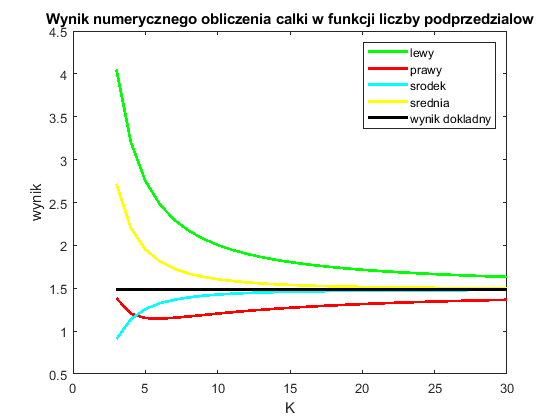



N=30;
x2=Q:N;
for k=x2
    d_podprze=(b-a)/k;
    pkt_l=(a:d_podprze:b-d_podprze);
    pkt_r=(a+d_podprze:d_podprze:b);
    pkt_m=(a+d_podprze/2:d_podprze:b-d_podprze/2);
    calka_num_l(k-Q+1)=sum(double(f(pkt_l)))*d_podprze;
    calka_num_r(k-Q+1)=sum(double(f(pkt_r)))*d_podprze;
    calka_num_m(k-Q+1)=sum(double(f(pkt_m)))*d_podprze;
    calka_num_mv(k-Q+1)=sum(double(f(pkt_l)+f(pkt_r))/2)*d_podprze;
    blad_l(k-Q+1)=abs((calka_num_l(k-Q+1)-calka_dokladna)/calka_dokladna);
    blad_r(k-Q+1)=abs((calka_num_r(k-Q+1)-calka_dokladna)/calka_dokladna);
    blad_m(k-Q+1)=abs((calka_num_m(k-Q+1)-calka_dokladna)/calka_dokladna);
    blad_mv(k-Q+1)=abs((calka_num_mv(k-Q+1)-calka_dokladna)/calka_dokladna);
end
figure()
plot(x2,calka_num_l,'g',x2,calka_num_r,'r',x2,calka_num_m,'c', x2,calka_num_mv,'y',x2, linspace(calka_dokladna,calka_dokladna,N-Q+1),'k', 'lineWidth', 2)
title 'Wynik numerycznego obliczenia calki w funkcji liczby podprzedzialow'
xlabel 'K'
ylabel 'wynik'
legend('lewy', 'prawy', 'srodek', 'srednia', 'wynik dokladny')

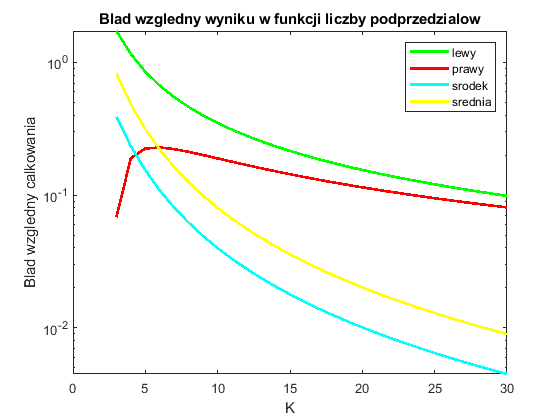

figure()
semilogy(x2,blad_l,'g',x2,blad_r,'r',x2,blad_m,'c', x2,blad_mv,'y', 'lineWidth', 2)
title 'Blad wzgledny wyniku w funkcji liczby podprzedzialow'
xlabel 'K'
ylabel 'Blad wzgledny calkowania'
legend('lewy', 'prawy', 'srodek', 'srednia')